% Parámetros
fs = 4e9;               % Frecuencia de muestreo (4 GHz)
t = 0:1/fs:1e-6;        % Tiempo total: 1 µs
f_in = 400e6;           % Frecuencia de entrada (400 MHz)

% Señal senoidal
x = cos(2*pi*f_in*t);

% FFT con ventana de Hann
N = length(x);
x_win = x .* hann(N)';          % Aplicar ventana para reducir leakage
X = fft(x_win);
X_mag = abs(X(1:N/2));          % Magnitud de la mitad positiva

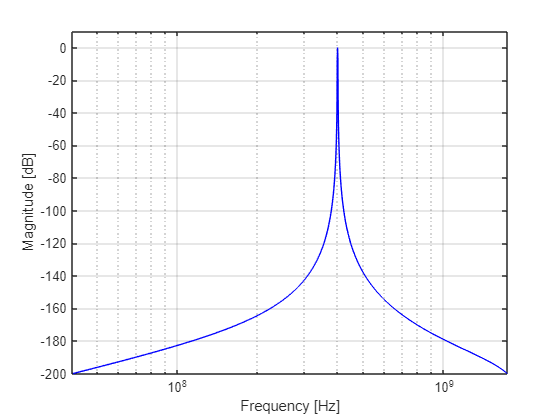

X_db = 20*log10(X_mag / max(X_mag)); % Normalización a 0 dB
f = (0:N/2-1)*(fs/N);           % Eje de frecuencia

% Graficar
figure;
plot(f, X_db, 'b'); grid on;
xlabel('Frequency [Hz]');
ylabel('Magnitude [dB]');
ylim([-200 10]);
set(gca, 'XScale', 'log');


% % Anotar fundamental (400 MHz)
% [~, idx_f0] = min(abs(f - f_in));
% hold on;
% plot(f(idx_f0), X_db(idx_f0), 'ro', 'LineWidth', 1.5);
% text(f(idx_f0), X_db(idx_f0)+5, sprintf('fin: %.0fMHz\\nAmplitude: %.2fdB', f(idx_f0)/1e6, X_db(idx_f0)), 'Color', 'k');
% 
% % Anotar armónico 3 (1200 MHz)
% f3 = 3*f_in;
% [~, idx_f3] = min(abs(f - f3));
% plot(f(idx_f3), X_db(idx_f3), 'go', 'LineWidth', 1.5);
% text(f(idx_f3), X_db(idx_f3)+5, sprintf('3^{rd} harmonic: %.0fMHz\\nAmplitude: %.2fdB', f(idx_f3)/1e6, X_db(idx_f3)), 'Color', 'k');
% 
% title('Espectro de la señal con armónicos');
